# Discrete time models and discrete PID controller design in MATLAB

Control is commonly implemented in discrete time. In order to be able to analyse behaviour in discrete time the user needs some understanding of discrete time models and how these can be handled in MATLAB. Often discrete models can be treated using Z-transforms which MATLAB handles formally using tools in the control toolbox. The basic definition and usage of such discrete models is discussed in files ***discrete_models_and_usage.mlx***

***discretization_and_bode.mlx***

This file then focuses on how PID  design can be performed in the discrete case using a pole cancellation technique.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

                                                                        

File written by J.A.Rossiter, University of Sheffield 

and  Ruth Bars, Budapest University of Technology and Economics

References: 

- Control Engineering: MATLAB Exercises, by L. Keviczky, R. Bars, J. Hetthéssy, Cs. Bányász, Springer, 2019

- Control Engineering, by    L. Keviczky, R. Bars, J. Hetthéssy, Cs. Bányász, Springer, 2019                   

## Table of contents

- Technical and mathematical background

- Pulse transfer functions of some basic elements

- Frequency function and BODE diagram of a sampled system

- Discrete PID controllers

- Design of PID controllers using pole cancellation

## 1.Technical and mathematical background

This file does not discuss details such as the zero-order-hold and sampler in detail.

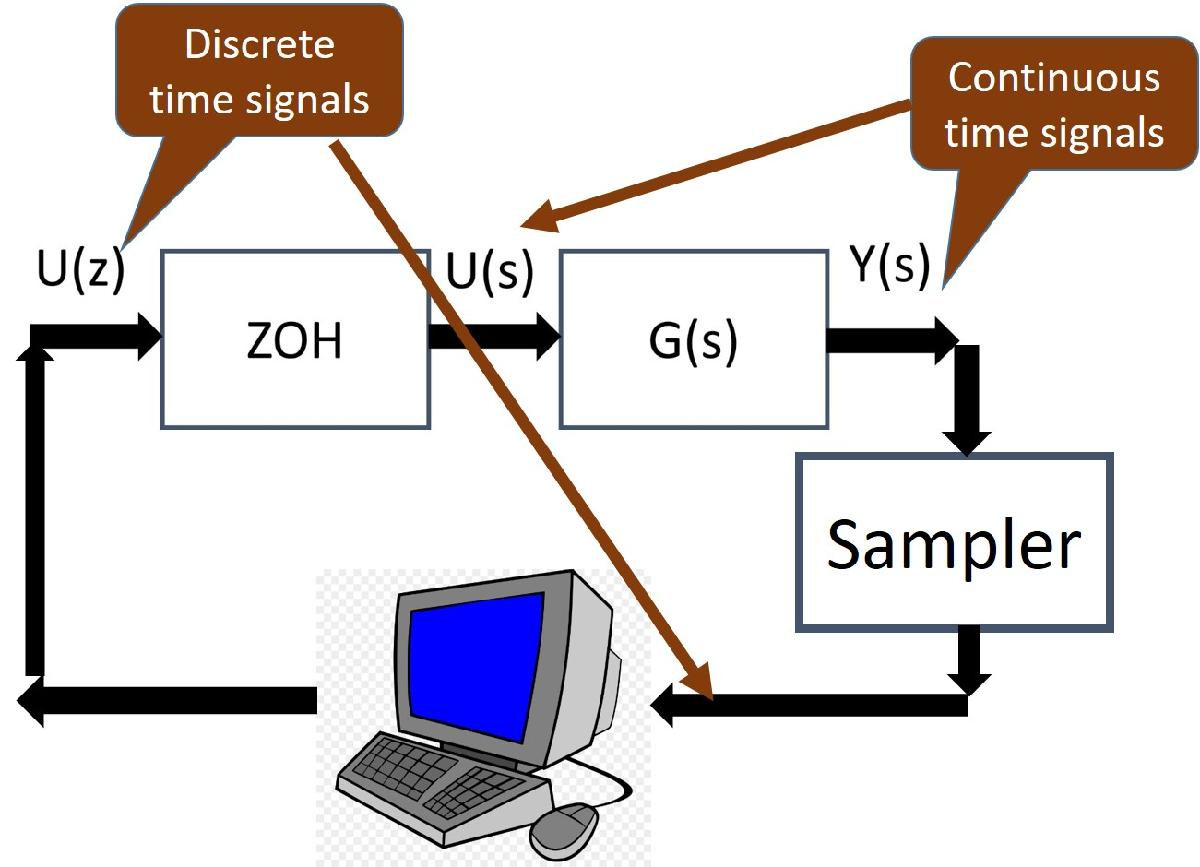

- The discretised system model *G(z)* (also called the pulse transfer function) includes the ZOH (zero-order-hold) and sampler. 

- The compensator *M(z)* works entirely in discrete time (e.g. represented by the computer above).

A  z-transform model could be represented as:


$$\left(1+a\left(1\right)z^{-1} +a\left(2\right)z^{-2} +\cdots \right)y\left(k\right)=\left(b\left(1\right)z^{-1} +b\left(2\right)z^{-2} +\cdots \right)u\left(k\right)\;\Rightarrow Y\left(z\right)=\left\lbrack \frac{b\left(1\right)z^{-1} +b\left(2\right)z^{-2} +\cdots }{1+a\left(1\right)z^{-1} +a\left(2\right)z^{-2} +\cdots }\right\rbrack U\left(z\right)$$


This type of model equation can be used for both the system model *G(z)* and the compensator model *M(z)*. In general terms with a standard closed-loop we would deploy equations such as:


$$Y\left(z\right)=G\left(z\right)U\left(z\right)\;\;\;\;\;\;\;\;U\left(z\right)=M\left(z\right)\left\lbrack R\left(z\right)-Y\left(z\right)\right\rbrack$$
  

with $R\left(z\right)$ the target, $Y\left(z\right)$ the output and  $U\left(z\right)$ the input, $G\left(z\right)$ the system and $M\left(z\right)$ the compensator.

The assumption is made that the model may be first provided in continuous time form, as most real systems are continuous. Sampling and holding introduces extra delay into the system, its value is typically between the half and the entire sampling time T. The compensator is discrete, its output values are calculated in the sampling instants and the zero order hold ZOH provides the continuous input at the input of the process. 

The block diagram of the control system is given below where the parts within the dotted box are approximated as $G\left(z\right)$.

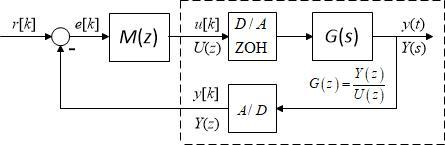 

Here controller design will be executed in the z discrete operator domain, determining the pulse transfer function M(z) of the controller which ensures the prescribed quality specifications given for the control system. Quality specifications can be formulated in the frequency domain. It will be demonstrated that till $\omega =\frac{1}{T}$ the continuous and the discrete frequency functions are close to each other, so PID-like controller design can be executed for the discrete case based on continuous time frequency considerations. Then the u[k] control signal can be calculated recursively from the designed pulse transfer function of the controller.

## 2. Pulse transfer functions of some basic elements 

It is convenient to be familiar with the  pulse transfer functions of some basic continuous elements in pole-zero form, assuming a zero order hold. Some common systems are summarised here, but without the detailed derivations.

- The transfer function of a pure dead time (pure delay of $T_d \;$seconds) element is $G\left(s\right)=e^{-sT_d }$. With sampling time ***T*** its pulse transfer function is $G\left(z\right)=z^{-k}$, where $k=\frac{T_d }{T}$ (typically we assume only integer values for ***k***).

- The transfer function of a first order lag element is  $G\left(s\right)=\frac{1}{1+sT_1 }$  and the pulse transfer function including the zero order hold is obtained as:    $G\left(z\right)=\frac{1-e^{-\frac{T}{T_1 }} }{z-e^{-\frac{T}{T_1 }} }$.

- The transfer function of a second order lag element is  $G\left(s\right)=\frac{1}{\left(1+sT_1 \right)\left(1+sT_2 \right)}$  and the pulse transfer function including a zero order hold is obtained in form $G\left(z\right)=k\frac{z+\sigma }{\left(z-e^{-\frac{T}{T_1 }} \right)\left(z-e^{-\frac{T}{T_2 }} \right)}$. 

- With 3 lags the pulse transfer function has 3 poles and 2 zeros.

- The transfer function of an integrator is $G\left(s\right)=\frac{1}{s}$, the pulse transfer function is $\frac{T}{z-1}$.

The parameters in the pulse transfer functions depend on the continuous parameters and the sampling time.

Example code for determining these typical pulse transfer functions is given below. Note that the answers depend on the choice of sample time ***T ***and use the MATLAB command*** c2d.m. ***For completeness a comparison of step responses (discrete vs continuous) is also presented, where, as expected, the values coincide at the sampling points (same system and same input).

disp('CONTINUOUS AND DISCRETE TRANSFER FUNCTIONS')

CONTINUOUS AND DISCRETE TRANSFER FUNCTIONS


disp('First order lag element')

First order lag element


s=zpk('s');
G1=1/(1+0.1*s)

G1 =
 
    10
  ------
  (s+10)
 
Continuous-time zero/pole/gain model.
Model Properties


T=0.1;           %sampling time
Gd1=c2d(G1,T)    %or alternatively Gd1=c2d(G1,T,'zoh'), discrete model

Gd1 =
 
   0.63212
  ----------
  (z-0.3679)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.
Model Properties



disp(' ***********************')

 ***********************


disp('Second order lag element')

Second order lag element


G2=1/((1+0.1*s)*(1+0.2*s))

G2 =
 
       50
  ------------
  (s+10) (s+5)
 
Continuous-time zero/pole/gain model.
Model Properties


Gd2=c2d(G2,T)

Gd2 =
 
   0.15482 (z+0.6065)
  ---------------------
  (z-0.6065) (z-0.3679)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.
Model Properties


[zerod2,poled2,kd2]=zpkdata(Gd2,'v') %extracting zeros and poles

zerod2 = -0.6065

kd2 = 0.1548


disp(' ***********************')

 ***********************


disp('Third order lag element')

Third order lag element


G3=1/((1+0.1*s)*(1+0.2*s)*(1+0.3*s))

G3 =
 
          166.67
  ----------------------
  (s+10) (s+5) (s+3.333)
 
Continuous-time zero/pole/gain model.
Model Properties


Gd3=c2d(G3,T)

Gd3 =
 
    0.017792 (z+0.167) (z+2.396)
  --------------------------------
  (z-0.7165) (z-0.6065) (z-0.3679)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.
Model Properties


[zerod3,poled3,kd3]=zpkdata(Gd3,'v')

kd3 = 0.0178


disp(' ***********************')

 ***********************


disp('Integrator')

Integrator


G4=1/s

G4 =
 
  1
  -
  s
 
Continuous-time zero/pole/gain model.
Model Properties


Gd4=c2d(G4,T)

Gd4 =
 
   0.1
  -----
  (z-1)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.
Model Properties


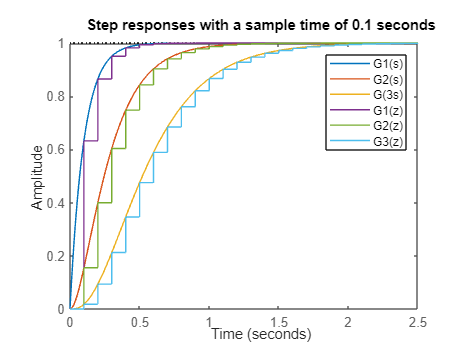


% Plot the step responses
step(G1,G2,G3,Gd1,Gd2,Gd3) 
legend('G1(s)','G2(s)','G(3s)','G1(z)','G2(z)','G3(z)')
title(['Step responses with a sample time of ',num2str(T),' seconds'])

## 3. Frequency function and Bode diagram of a sampled system

The frequency function of the pulse transfer function is obtained by substituting $z=e^{j\omega T}$, where ***T*** is the sampling time. As an example let us consider the pulse transfer function and the frequency function of a first order lag element.

The transfer function is  $G\left(s\right)=\frac{1}{1+sT_1 }$  and the pulse transfer function supposing zero order hold is obtained as    $G\left(z\right)=\frac{1-e^{-\frac{T}{T_1 }} }{z-e^{-\frac{T}{T_1 }} }$. The frequency function is given as


$$G\left(z=e^{j\omega T} \right)=\frac{1-e^{-\frac{T}{T_1 }} }{e^{j\omega T} -e^{-\frac{T}{T_1 }} }\approx \frac{1-\left(1-\frac{T}{T_1 }+\frac{1}{2}{\left(\frac{T}{T_1 }\right)}^2 -\ldotp \ldotp \ldotp \right)}{1+j\omega T-\frac{{\left(\omega T\right)}^2 }{2}+\ldotp \ldotp \ldotp -\left(1-\frac{T}{T_1 }+\frac{1}{2}{\left(\frac{T}{T_1 }\right)}^2 -\ldotp \ldotp \ldotp \right)}$$


where the function can be approximated by its Taylor series.

If  $T<T_1$ and $\omega T<1$  the higher powers of $\frac{T}{T_1 }$and $\omega T$ can be neglected and the frequency function of the sampled system is approximately the same as the frequency function of the continuous system, that is, $G\left(z=e^{j\omega T} \right)\approx \frac{1}{1+j\omega T_1 }e^{-j\omega T_a }$ where the neglected terms can be considered by the additional $T_a$ delay whose value is between the half and the entire sampling time. So the approximation is valid until $\omega =\frac{1}{T}$.

The code below gives a simple example of a sample frequency range of comparing the gain and phase diagrams of a continuous and discrete first order system. The transfer function is  $G\left(s\right)=\frac{1}{1+0\ldotp 1s}$ and the sampling time is *T=0.1.*

**WARNING**: The maximum frequency for a discrete system is $w=\frac{\pi }{T}\;$although ideally far lower values would be used.

disp('***********************')

***********************


disp('Section 3 below')

Section 3 below


disp('COMPARING CONTINUOUS AND DISCRETE FREQUENCY FUNCTIONS')

COMPARING CONTINUOUS AND DISCRETE FREQUENCY FUNCTIONS


s=zpk('s');
G=1/(1+0.1*s)

G =
 
    10
  ------
  (s+10)
 
Continuous-time zero/pole/gain model.
Model Properties


T=0.1;
wmax = pi/T   % maximum frequency

wmax = 31.4159

Gd=c2d(G,T)

Gd =
 
   0.63212
  ----------
  (z-0.3679)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.
Model Properties


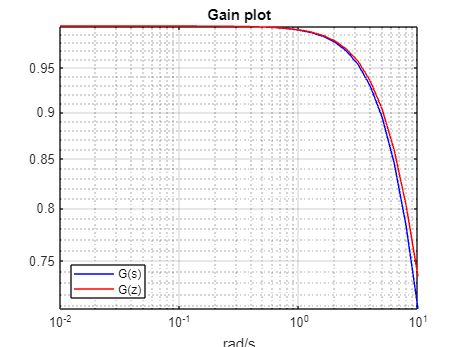

w=logspace(-2,1,wmax);
[mags,phases]=bode(G,w);
[magd,phased]=bode(Gd,w);
loglog(w,mags(:),'b',w,magd(:),'r'),grid
legend('G(s)','G(z)','Location','Southwest')
title('Gain plot')
xlabel('rad/s')

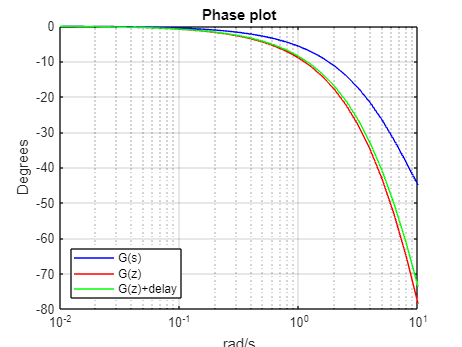


phasewithdel=phases(:)-w'*(T/2)*180/pi;
semilogx(w,phases(:),'b',w,phased(:),'r',w,phasewithdel,'g'),grid
legend('G(s)','G(z)','G(z)+delay','Location','Southwest')
title('Phase plot')
xlabel('rad/s')
ylabel('Degrees')

It is seen that up to around $\omega =10$ the continuous and discrete amplitudes of the Bode amplitude diagram are almost coinciding, while in the phase angles a larger difference can be observed which is significant beyond around $\omega =1$. Adding the phase coming from the half sampling time delay, the phase angles become closer to each other.

**Remark**: Controller design for discrete systems can be based on the frequency considerations for continuous systems. As sampling introduces extra delay whose value is about T, the cut-off frequency can be located to less values than 1/T, where the continuous and the discrete frequency functions are close to each other. For systems containing dead time (here the dead time of the continuous process plus the extra delay coming from sampling) the cut-off frequency calculated from the frequency function of the open-loop, should be located at $\omega_c \approx \frac{1}{2\left(T_d +T\right)}$ in the range of slope -20dB/decade on the approximate Bode amplitude diagram to ensure phase margin of about  60°. For controller design considerations the frequency range until 1/T should be considered.

## 4. Discrete PID controllers exploiting pole cancellations

The controller algorithms can be given immediately in discrete form by their pulse transfer functions. The denominator of the pulse transfer functions of lag elements contain factors of the form: 


$$\left(z-e^{-\frac{T}{T_1 }} \right)\left(z-e^{-\frac{T}{T_2 }} \right)\ldotp \ldotp \ldotp$$


The controllers may apply so-called pole cancellation techniques, for example cancelling the "bad" poles of the process and introducing "better" poles instead.

The discrete *P, PI, PD, PID* algorithms can be given by the following pulse transfer functions:

    P (proportional) controller:    ***M*****(*****z*****)=*****A***

    PI controller:                        $M\left(z\right)=A\frac{z-e^{-\frac{T}{T_1 }} }{z-1}$ ;    The biggest time constant of the process is

                                                                                     cancelled and an integrating effect is 

                                                                                     introduced instead.

    PD controller:                     $M\left(z\right)=A\frac{z-e^{-\frac{T}{T_2 }} }{z-e^{-\frac{T}{T_2^* }} }$ ;     where  $T_2^*$<$T_2$.  An unfavourable time 

                                                                                      constant of the process is cancelled and a 

                                                                                     smaller time constant is introduced instead.                                                                                   

    Ideal PD controller:           $M\left(z\right)=A\frac{z-e^{-\frac{T}{T_2 }} }{z}$ ;    The ideal differentiating effect in discrete form  

                                                                                   is realizable as the overexcitation is a finite  

                                                                                   value.                                                                         

    PIPD controller with ideal PD effect:                $M\left(z\right)=A\frac{z-e^{-\frac{T}{T_1 }} }{z-1}\frac{z-e^{-\frac{T}{T_2 }} }{z}$

The gain $A$ of the controller can be designed to ensure a prescribed phase margin (e.g. ${\approx 60}^{\circ }$).

The controllers are realized by their difference equations. For example, the difference equation of a PI controller is:

            
$$u\left\lbrack k\right\rbrack =A\left(e\left\lbrack k\right\rbrack -p\;e\left\lbrack k-1\right\rbrack \right)+u\left\lbrack k-1\right\rbrack ;\;\;\;\;\;\;\;\;\;p=e^{-\frac{T}{T_1 }}$$


The difference equation of the controller is a recursive relationship which can be realised in real time.  *k* denotes the actual time point. Thus the actual value of the manipulated variable is calculated from the actual and previous value of the error signal and from the previous value of the manipulated variable.

***Remark***: Instead of using parallel connected P, I and D controllers it is adviced to apply serially connected PI and PD controllers. This is advantageous in controller design.

***Remark***: Multiple *PI* and *PD* effects can also be applied if the limit given for the control signal *u *is not exceeded.

**Further reading**: Control Engineering, by    L. Keviczky, R. Bars, J. Hetthéssy, Cs. Bányász, Springer, 2019.

## 5. Design of PID controllers using pole cancellation

The controller is designed to ensure the quality specifications prescribed for the closed loop control system.

If the requirement is to track a step reference signal without steady state error, then an integrator should be included in the open loop transfer function. If the process model does not contain integrator, then an integrator should appear in the controller. 

With pole cancellation technique the unfavourable poles of the process can be cancelled by the zeros of the controller which introduces more favourable poles instead. Zeros of the process are not touched.

For illustration purposes in this file, the gain of the controller is set to ensure ~60° phase margin, which is expected to correspond to approximately 10% or less overshoot in the step response of the closed loop system. The phase margin is set on the basis of the frequency function of the open loop. A good approximation is that the cut-off frequency should be located approximately at $\omega_c \approx 1/\left\lbrack 2\left(T_d +T\right)\right\rbrack ,\;$where $T_d$ is the dead time and *T*  is the sampling time. The sampling time acts as an additional small dead time. Quick design can be made on the basis of the Bode amplitude diagram of the open loop of the continuous system, as it approximates closely enough the Bode diagram of the discrete system in the considered frequency range. 

The settling time of the output of the control system is approximated as $\frac{3}{\omega_c }<t_s <\frac{10}{\omega_c }$ . The higher the cut-off frequency the faster  the process. But the dead time and the samping time give a limit for the acceleration. In practice the control signal (the manipulated variable) is restricted, its value should not exceed a given limit. This value should be checked. If it is exceeded then the design should be repeated so that the compensator makes less aggressive demands of the actuator, e.g. by increasing the prescribed phase margin.  

#### 5.1 Controller design for a third order proportional process

The continuous process is given by transfer function 

$G\left(s\right)=\frac{1}{\left(1+10s\right)\left(1+4s\right)\left(1+s\right)}$; The sampling time is T=1.

Design discrete P, PI, PD, PIPD controllers for a 60° phase margin AND to achieve the desired pole cancellation of the slowest pole or poles, where applicable.

Show the step responses of the output and the control signal. First define the transfer function and the pulse transfer function of the process.

disp('*******************************************')

*******************************************


disp('SECTION 5.1 BELOW')

SECTION 5.1 BELOW


s=zpk('s');                      %Give the s operator
G=1/((1+10*s)*(1+4*s)*(1+s))

G =
 
          0.025
  ----------------------
  (s+0.1) (s+0.25) (s+1)
 
Continuous-time zero/pole/gain model.
Model Properties


T=1;
Gd=c2d(G,T,'zoh')               %Determine the pulse transfer function

Gd =
 
   0.0030174 (z+0.188) (z+2.712)
  --------------------------------
  (z-0.9048) (z-0.7788) (z-0.3679)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.
Model Properties


[zd,pd,kd]=zpkdata(Gd,'v')      %Extracting the zero, pole and gain

kd = 0.0030

z=zpk('z',T);                   %Give the z operator

The pulse transfer function is:


$$\textrm{Gd}\left(z\right)=\frac{0\ldotp 0030174\left(z+0\ldotp 188\right)\left(z+2\ldotp 712\right)}{\left(z-0\ldotp 9048\right)\left(z-0\ldotp 7788\right)\left(z-0\ldotp 3679\right)}$$


**STEP 1**: Define 4 different compensators as discussed in section 4 and remove (cancel) pole factors from the loop transfer function introducing more favourable poles instead. Use unity gains for now as the gains will be defined in step 2.

disp('THE CONTROLLERS WITH UNITY GAIN and REQUIRED POLE CANCELLATION')

THE CONTROLLERS WITH UNITY GAIN and REQUIRED POLE CANCELLATION


Ap=1;Api=1;Apd=1;Apid=1;
disp('Proportional controller')

Proportional controller


Mp=1

Mp = 1

disp('PI controller')

PI controller


Mpi=(z-pd(1))/(z-1)

Mpi =
 
  (z-0.9048)
  ----------
    (z-1)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.
Model Properties


disp('Ideal PD controller')

Ideal PD controller


Mpd=(z-pd(2))/z

Mpd =
 
  (z-0.7788)
  ----------
      z
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.
Model Properties


disp('PIPD controller')

PIPD controller


Mpipd=Mpi*Mpd

Mpipd =
 
  (z-0.9048) (z-0.7788)
  ---------------------
         z (z-1)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.
Model Properties



disp('THE LOOP TRANSFER FUNCTIONS AFTER CANCELLING POLES')

THE LOOP TRANSFER FUNCTIONS AFTER CANCELLING POLES


Lp=Gd

Lp =
 
   0.0030174 (z+0.188) (z+2.712)
  --------------------------------
  (z-0.9048) (z-0.7788) (z-0.3679)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.
Model Properties


Lpi=minreal(Mpi*Gd,0.001)  %with command minreal the common factors

Lpi =
 
  0.0030174 (z+0.188) (z+2.712)
  -----------------------------
   (z-1) (z-0.7788) (z-0.3679)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.
Model Properties


                           %in the numerator and denominator are cancelled
Lpd=minreal(Mpd*Gd,0.001)

Lpd =
 
  0.0030174 (z+0.188) (z+2.712)
  -----------------------------
     z (z-0.9048) (z-0.3679)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.
Model Properties


Lpipd=minreal(Mpipd*Gd,0.001)

Lpipd =
 
  0.0030174 (z+0.188) (z+2.712)
  -----------------------------
       z (z-1) (z-0.3679)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.
Model Properties


**STEP 2:** Analyse the frequency responses and margins from the open-loops for each controller in turn. We want to select the compensator gains to give a 60 degree phase margin so it is necessary to identify the corresponding gains by hand, for example by plotting the Bode diagrams and using a zoom around -120 degrees to find the required frequency and thus gain uplift. [See files ***proportional_design_phase_margin*** and ***proportional_design_with_bode*** for more on this technique or indeed use tools like ***sisotool***.]

For each system the gains required to achieve a 60 degree phase margin are:

- Proportional controller: Mp=1/0.3365

- PI controller: Api=1/0.8905

- Ideal PD controller: Apd=1/0.0497

- PIPD controller: Apid=1/0.0756

disp('CALCULATING THE GAINS OF THE P CONTROLLER')

CALCULATING THE GAINS OF THE P CONTROLLER


%The frequency vector is given till 1/T=1
w=logspace(-2,0,200);
%Frequency function with the proportional controller
[mag,phase]=bode(Lp,w);
Table=[mag(:),phase(:),w']
%evaluate the table:The phase angle is -119.99° at w=0.2026. The gain here is 0.3365
%The cut-off frequency is located at this w value if the gain is Ap=1/0.3365

The gains of the other controllers can be calculated similarly.

You can check the efficacy of the following using the commands below:

disp(['Margins for the proportional compensator']);

Margins for the proportional compensator


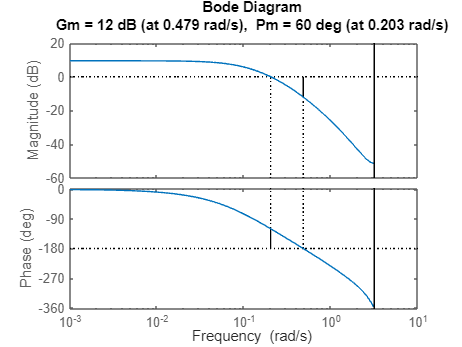

Mp=1/0.3365;
margin(Gd*Mp);

disp(['Margins for the PI compensator']);

Margins for the PI compensator


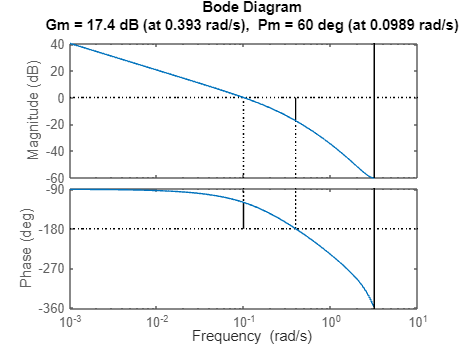

Api=1/0.8905; Mpi=Mpi*Api;
margin(Gd*Mpi);

disp(['Margins for the PD compensator']);

Margins for the PD compensator


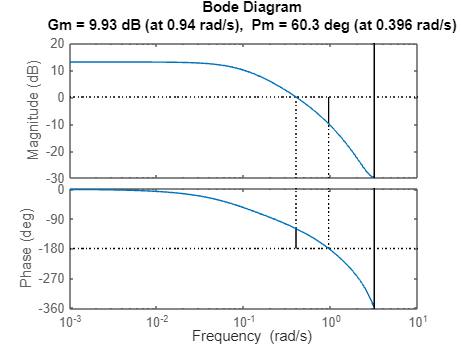

Apd=1/0.0497; Mpd=Mpd*Apd;
margin(Gd*Mpd);

disp(['Margins for the PIPD compensator']);

Margins for the PIPD compensator


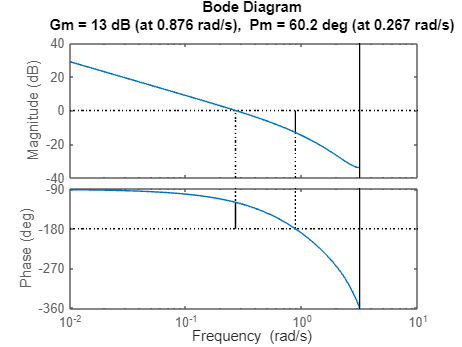

Apid=1/0.0756; Mpipd = Mpipd*Apid;
margin(Gd*Mpipd);

**STEP 3**: Check the step responses of the closed systems are behaving as expected. For convenience we overlay all the plots here so the user can evaluate the differences from using each strategy.

disp('CALCULATING THE STEP RESPONSES OF THE COMPENSATED SYSTEMS')

CALCULATING THE STEP RESPONSES OF THE COMPENSATED SYSTEMS


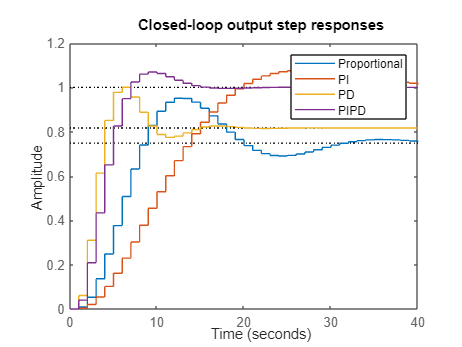

Gp = feedback(Gd*Mp,1);
Gpi = feedback(Gd*Mpi,1);
Gpd = feedback(Gd*Mpd,1);
Gpipd = feedback(Gd*Mpipd,1);
step(Gp,Gpi,Gpd,Gpipd,40);
title('Closed-loop output step responses')
legend('Proportional','PI','PD','PIPD')

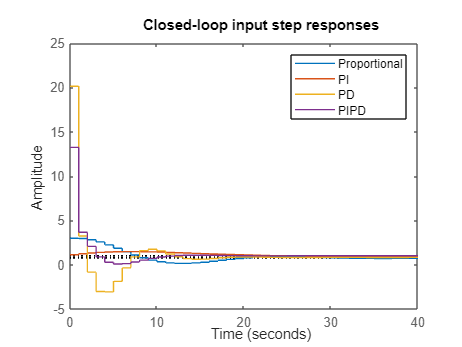


Gpu = feedback(Mp,Gd);
Gpiu = feedback(Mpi,Gd);
Gpdu = feedback(Mpd,Gd);
Gpipdu = feedback(Mpipd,Gd);
step(Gpu,Gpiu,Gpdu,Gpipdu,40);
title('Closed-loop input step responses')
legend('Proportional','PI','PD','PIPD')

It can be seen that with the P and PD controllers there is a static error in steady state. PD and PIPD controllers provide faster behaviour with the price of higher actuating control signals.

***Remark***: The output values are calculated only in the sampling points.The plot command connects these points with horizontal lines. To get the output values of the continuous system between the sampling points it is necessary to calculate these inner values or to use the simulink program.

**Remark**: Using ***feedback.m***, the closed-loop transfer functions may contain cancelling pole-zero pairs which can be removed with ***minreal.m***

#### 5.2 Controller design for a dead time process

The continuous system is given by a first order lag element with significant dead time.

Its transfer function is

$G\left(s\right)=\frac{1}{1+4s}e^{-8s}$ . The sampling time is T=2.

Design a discrete PI controller ensuring approximately 60° phase margin.

The cut-off frequency should be approximately at $\frac{1}{2\left(8+2\right)}$=0.05

**Step 1**: First define the system in MATLAB.

disp('***************************************************')

***************************************************


disp('Section 5.2 below')

Section 5.2 below


disp('CONTROLLER DESIGN FOR A FIRST ORDER LAG ELEMENT WITH DEAD TIME')

CONTROLLER DESIGN FOR A FIRST ORDER LAG ELEMENT WITH DEAD TIME


s=zpk('s');
T=2;
z=zpk('z',T);
disp('The continuous system')

The continuous system


G=1/(1+4*s)

G =
 
    0.25
  --------
  (s+0.25)
 
Continuous-time zero/pole/gain model.
Model Properties


Td=8;
Gd=c2d(G,T,'zoh');
[zd,pd,kd]=zpkdata(Gd,'v');
disp('The discrete system')

The discrete system


Gdd=Gd*z^-4

Gdd =
 
     0.39347
  --------------
  z^4 (z-0.6065)
 
Sample time: 2 seconds
Discrete-time zero/pole/gain model.
Model Properties


**Step 2:** Define the PI compensator by using a generic compensator as in section 4 to cancel the slowest pole and then finding the gain to give a 60 degree phase margin. 

%The PI controller
disp('PI compensator and loop transfer function: note the cancellation')

PI compensator and loop transfer function: note the cancellation


Md=(z-pd(1))/(z-1);
Ad = 0.294;
Md=Md*Ad

Md =
 
  0.294 (z-0.6065)
  ----------------
       (z-1)
 
Sample time: 2 seconds
Discrete-time zero/pole/gain model.
Model Properties


Ld=minreal(Md*Gdd,0.001)

Ld =
 
   0.11568
  ---------
  z^4 (z-1)
 
Sample time: 2 seconds
Discrete-time zero/pole/gain model.
Model Properties


**Step 3:** Confirm the margins are as expected and view the closed-loop responses.

disp('Margins and closed-loop responses')

Margins and closed-loop responses


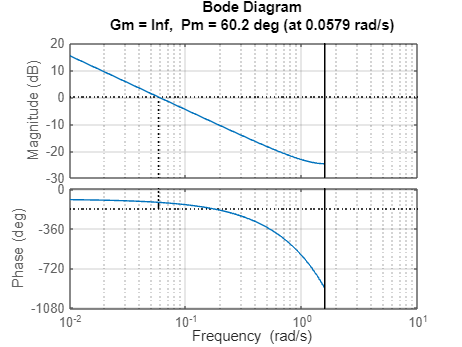

margin(Ld); grid

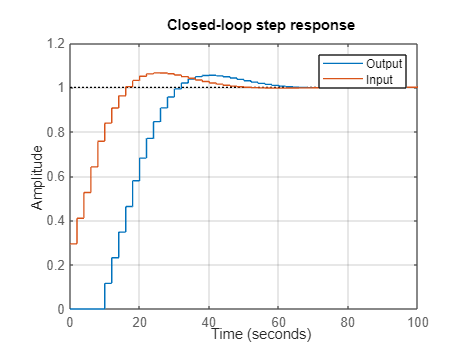

GC1 = feedback(Ld,1);
GC2 = feedback(Md,Gdd);
step(GC1,GC2,100),grid
title('Closed-loop step response')
legend('Output','Input')

***Remark***: The dead time restricts the acceleration of the closed loop system. The settling process with PI controller is slow.

#### 5.3 Controller design for a nonminimum-phase process

The continuous system is given by following transfer function:

$G\left(s\right)=\frac{1-s}{\left(1+s\right)\left(1+2s\right)}$ . The sampling time is T=0.5.

Design a discrete PIPD controller ensuring approximately 60° phase margin.

**Step 1**: First define the system in MATLAB.

disp('***************************************************')

***************************************************


disp('Section 5.3 below')

Section 5.3 below


disp('CONTROLLER DESIGN FOR A NONMINIMUM-PHASE PROCESS')

CONTROLLER DESIGN FOR A NONMINIMUM-PHASE PROCESS


s=zpk('s')

s =
 
  s
 
Continuous-time zero/pole/gain model.
Model Properties


disp('The continuous system')

The continuous system


G=(1-s)/((1+s)*(1+2*s))

G =
 
   -0.5 (s-1)
  -------------
  (s+1) (s+0.5)
 
Continuous-time zero/pole/gain model.
Model Properties


disp('The sampling time')

The sampling time


T=0.5

T = 0.5000

z=zpk('z',T)

z =
 
  z
 
Sample time: 0.5 seconds
Discrete-time zero/pole/gain model.
Model Properties


disp('The discrete system')

The discrete system


Gd=c2d(G,T)

Gd =
 
   -0.12334 (z-1.706)
  ---------------------
  (z-0.7788) (z-0.6065)
 
Sample time: 0.5 seconds
Discrete-time zero/pole/gain model.
Model Properties


[zd,pd,kd]=zpkdata(Gd,'v');
disp('Step responses of the continuous and the discrete plant')

Step responses of the continuous and the discrete plant


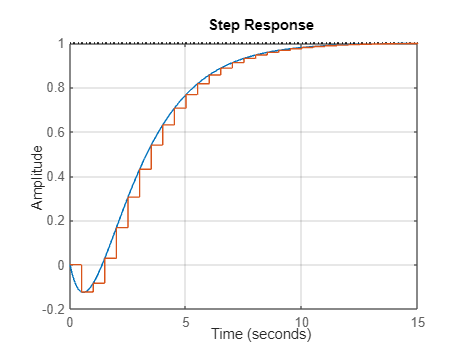

step(G,Gd,15),grid

**Step 2:** Define the PIPD compensator cancelling the poles and introducing an integrating effect and a smaller time constant, and then finding the gain to give approximately 60 degree phase margin (try different constant values for the controller pulse transfer function). 

%The discrete PIPD compensator
Ad=2.5          % Try also different gain valued

Ad = 2.5000

Md=Ad*(z-pd(1))*(z-pd(2))/(z*(z-1));
%The open-loop
Ld=minreal(Gd*Md,0.001)

Ld =
 
  -0.30835 (z-1.706)
  ------------------
       z (z-1)
 
Sample time: 0.5 seconds
Discrete-time zero/pole/gain model.
Model Properties


**Step 3:** View the closed-loop responses.

disp('Closed-loop responses')

Closed-loop responses


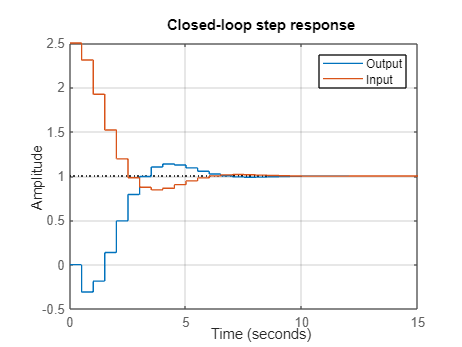

GC1 = feedback(Ld,1);
GC2 = feedback(Md,Gd);
step(GC1,GC2,15),grid
title('Closed-loop step response')
legend('Output','Input')

It can be seen that the settling time of the controlled process is smaller than the settling time of the process.

It is emphasized that the poles of the system were cancelled and an integrating effect and a differentiating effect have been introduced. The zero of the process remained untouched.

#### **APPENDIX A:  Step responses of the basic controllers** 

disp('******************************************************************')

******************************************************************


disp('Appendix A')

Appendix A


disp('STEP RESPONSE OF DISCRETE CONTROLLERS')

STEP RESPONSE OF DISCRETE CONTROLLERS


T=1;             %sampling time
z=zpk('z',T);    %defining the z operator
Ti=10;
A=2;
pdi=exp(-T/Ti);
Mpi=A*(z-pdi)/(z-1)

Mpi =
 
  2 (z-0.9048)
  ------------
     (z-1)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.
Model Properties


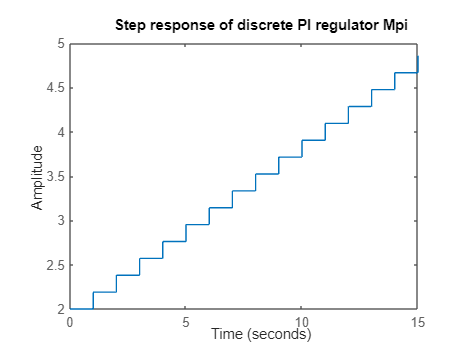

step(Mpi,15)
title('Step response of discrete PI regulator Mpi')



Td=10;
pdd=exp(-T/Td);
Mpd=A*(z-pdd)/z

Mpd =
 
  2 (z-0.9048)
  ------------
       z
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.
Model Properties


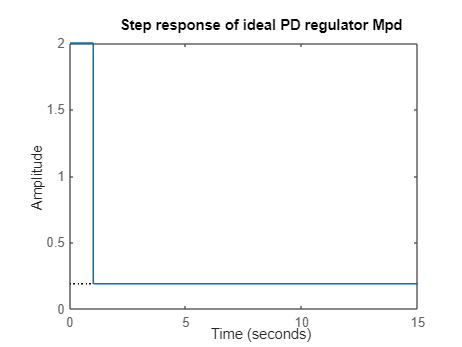

step(Mpd,15)
title('Step response of ideal PD regulator Mpd')



Td=10

Td = 10

Td1=1

Td1 = 1

pdd1=exp(-T/Td1);
Mpd1=A*(z-pdd)/(z-pdd1)

Mpd1 =
 
  2 (z-0.9048)
  ------------
   (z-0.3679)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.
Model Properties


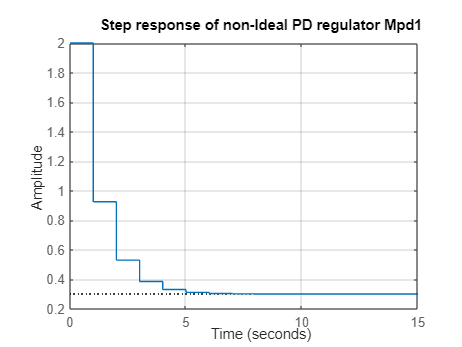

step(Mpd1,15),grid
title('Step response of non-Ideal PD regulator Mpd1')



Mpid=Mpi*Mpd/A

Mpid =
 
  2 (z-0.9048)^2
  --------------
     z (z-1)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.
Model Properties


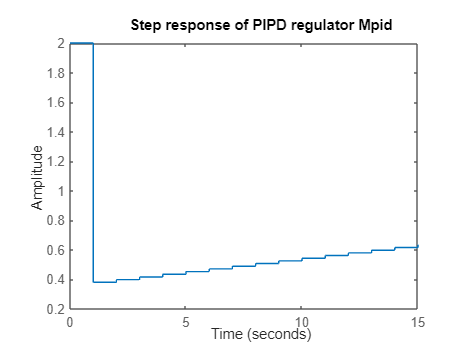

step(Mpid,15)
title('Step response of PIPD regulator Mpid')